clear; clc; close all;

**OFDM Parameters**

nfft = 1024;                    % nfft size equal to number of subcarriers
BW = 1000000000;                % Bandwidth of subcarriers (-F/2 F/2)
M = 4;                          % Baseband modulation order
cp_len = nfft/4;                % Cyclic Prefix length
ofdm_symbols =  1;               % Number of ofdm symbols to transmit
ebno_test = -5:2:30;
symbol_plot = 10;
rep = 4;                        % Repetition of pilots
pilot_index = [112:rep:913];    % Insert a pilot every 5 data sub-carriers
pilot_val = -0.7072+0.7072i;    % Set value of pilot subcarriers
data_index = 1:nfft;            % Index of data subcarriers
cw_tone = BW/nfft;
set_cw = 0; 
% Set 224 zero padded subcarriers: 111 on lower and upper subcarriers
% and 2 on each side of carrier
zp_index = [1:111,914:1024];
multipath = [0 1 0.02 0.8];            % Multipath taps
no_multi = [1 0 0 0];
%multipath = [1 0.3 0.5 0];
data_index([zp_index,pilot_index]) = [];
scs = BW/nfft;
cfo = scs/4;
plot_v = 0;
num_data_bits = length(data_index)*ofdm_symbols

num_data_bits =    601


**Modulate:**

[ofdm_signal,reference_pilot,mod_data,t,t2]=ofdm_transmit(nfft,BW,M,cp_len, ...
    ofdm_symbols,zp_index,pilot_index,0,1);
cw_signal = cos(2*pi*cw_tone*t2)'+i*sin(2*pi*cw_tone*t2)';

**Channel:**

ofdm_signal = exp(1i*2*pi*cfo*t2)'.*ofdm_signal;

**Scale:**

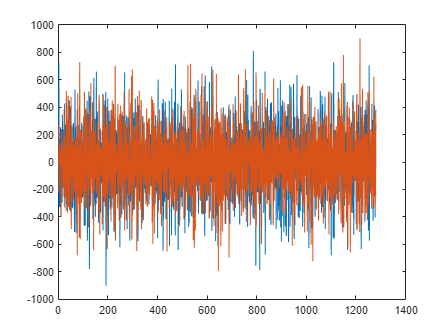

file = fopen('../../HW/modules/sim/equalizer_input_samples.txt','wt');
ofdm_scaled_signal = round(10000*ofdm_signal);
for i = 1:length(ofdm_signal)
    if i == length(ofdm_signal)
        fprintf(file,"%d, ",int16(real(ofdm_scaled_signal(i))));
        fprintf(file,"%d",int16(imag(ofdm_scaled_signal(i))));
    else
        fprintf(file,"%d, ",int16(real(ofdm_scaled_signal(i))));
        fprintf(file,"%d\n",int16(imag(ofdm_scaled_signal(i))));
    end
end

file = fopen('../../HW/modules/sim/cw_input_samples.txt','wt');
cw_scaled_signal = round(10000*cw_signal);
for i = 1:length(cw_signal)
    if i == length(cw_signal)
        fprintf(file,"%d, ",int16(real(cw_scaled_signal(i))));
        fprintf(file,"%d",int16(imag(cw_scaled_signal(i))));
    else
        fprintf(file,"%d, ",int16(real(cw_scaled_signal(i))));
        fprintf(file,"%d\n",int16(imag(cw_scaled_signal(i))));
    end
end
figure(),plot(real(ofdm_scaled_signal)),hold on,plot(imag(ofdm_scaled_signal))

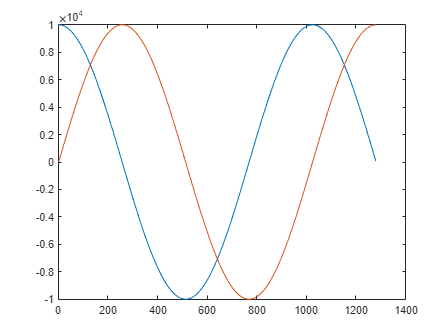

figure,plot(real(cw_scaled_signal)),hold on,plot(imag(cw_scaled_signal))

**Compare with Matlab: CFO Correction:**

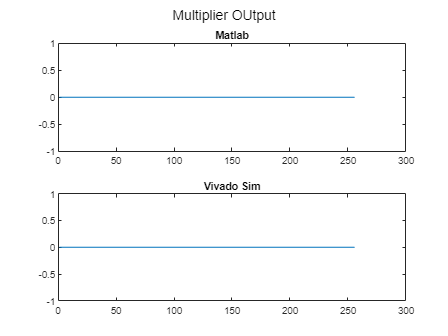

if set_cw == 1
    ofdm_scaled_signal = cw_scaled_signal;
end
ofdm_signal_par = reshape(ofdm_scaled_signal,[nfft+cp_len ofdm_symbols]);
cp_rm = ofdm_signal_par;
cp_rm(1:cp_len,:) = [];
ofdm_cfo_signal_par_eq = [];
cp_cfo_begin = ofdm_signal_par(1:cp_len);             % Obtain cyclic prefix at beginning of symbol
cp_cfo_end = (ofdm_signal_par(nfft+1:end));       % Obtain cyclic prefix at end of symbol
%cp_cfo_est = filter(cp_cfo_end,1,cp_cfo_begin);             % Correlate 
conj_val = conj(cp_cfo_begin);
tmp = complex(real(cp_cfo_end.*conj_val),imag(cp_cfo_end.*conj_val));

sum_val = sum(tmp);
angle_val = angle(sum_val);
normalized_cfo_est = 1/2/pi*angle_val;
cfo_est = normalized_cfo_est * scs;
freq = exp(1i*2*pi*cfo_est*t(1:nfft))';
ofdm_cfo_signal_par_eq = cp_rm(:).*freq;

file = fopen('../../HW/modules/sim/cp_begin_samples.txt','wt');
for i = 1:cp_len
    if i == cp_len
        fprintf(file,"%d, ",int16(real(cp_cfo_begin(i))));
        fprintf(file,"%d",int16(imag(cp_cfo_begin(i))));
    else
        fprintf(file,"%d, ",int16(real(cp_cfo_begin(i))));
        fprintf(file,"%d\n",int16(imag(cp_cfo_begin(i))));
    end
end
file = fopen('../../HW/modules/sim/cp_end_samples.txt','wt');
for i = 1:cp_len
    if i == cp_len
        fprintf(file,"%d, ",int16(real(cp_cfo_end(i))));
        fprintf(file,"%d",int16(imag(cp_cfo_end(i))));
    else
        fprintf(file,"%d, ",int16(real(cp_cfo_end(i))));
        fprintf(file,"%d\n",int16(imag(cp_cfo_end(i))));
    end
end
file = fopen('../../HW/modules/sim/cp_conj_samples.txt','wt');
for i = 1:cp_len
    if i == cp_len
        fprintf(file,"%d, ",int16(real(conj_val(i))));
        fprintf(file,"%d",int16(imag(conj_val(i))));
    else
        fprintf(file,"%d, ",int16(real(conj_val(i))));
        fprintf(file,"%d\n",int16(imag(conj_val(i))));
    end
end
file = fopen('../../HW/modules/sim/mult_samples.txt','wt');
for i = 1:cp_len
    if i == cp_len
        fprintf(file,"%d, ",int32(real(tmp(i))));
        fprintf(file,"%d",int32(imag(tmp(i))));
    else
        fprintf(file,"%d, ",int32(real(tmp(i))));
        fprintf(file,"%d\n",int32(imag(tmp(i))));
    end
end
file = fopen('../../HW/modules/sim/mult_verif_samples.txt','r');
tmp_out = [];
tmp_out1 = [];
for i = 1:cp_len
    tmp1 = fscanf(file,"%d");
    tmp2 = fscanf(file,",%d");
    tmp_out = complex(tmp1,tmp2);
    tmp_out1 = [tmp_out1 tmp_out];
end
figure(),subplot(2,1,1),plot(int32(real(tmp))),title('Matlab')
subplot(),subplot(2,1,2),plot(int32(real(tmp_out1))),title('Vivado Sim')
sgtitle('Multiplier OUtput')

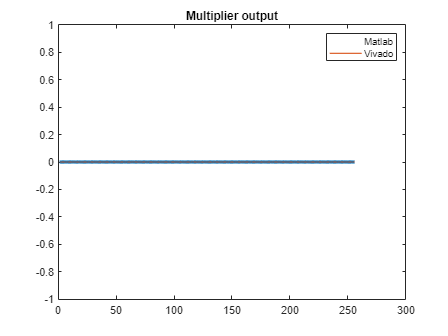

figure(),plot(int32(real(tmp)),'LineWidth',3),hold on,plot(int32(real(tmp_out1)),'LineWidth',1),title('Multiplier output'),legend('Matlab','Vivado')

file = fopen('../../HW/modules/sim/sum_samples.txt','wt');
for i = 1:ofdm_symbols
    if i == ofdm_symbols
        fprintf(file,"%d, ",int32(real(sum_val)));
        fprintf(file,"%d",int32(imag(sum_val)));
    else
        fprintf(file,"%d, ",int32(real(sum_val)));
        fprintf(file,"%d\n",int32(imag(sum_val)));
    end
end
file = fopen('../../HW/modules/sim/angle_samples.txt','wt');
for i = 1:ofdm_symbols
    if i == ofdm_symbols
        fprintf(file,"%d, ",angle_val);
    else
        fprintf(file,"%d, ",angle_val);
    end
end
file = fopen('../../HW/modules/sim/mixer_samples.txt','wt');
for i = 1:ofdm_symbols
    if i == ofdm_symbols
        fprintf(file,"%d, ",freq);
    else
        fprintf(file,"%d, ",freq);
    end
end